# Invers Kinematics: Key ideas

## Catching the idea 1 of 3

### Call a simple Two Link 

2R robot arm

clear
mdl_twolink
twolink

 
twolink = 
 
two link:: 2 axis, RR, stdDH, slowRNE                            
 - from Spong, Hutchinson, Vidyasagar;                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0, 0, 0), RPY/xyz = (0, 0, 90) deg                 
 


### Plotting twolink

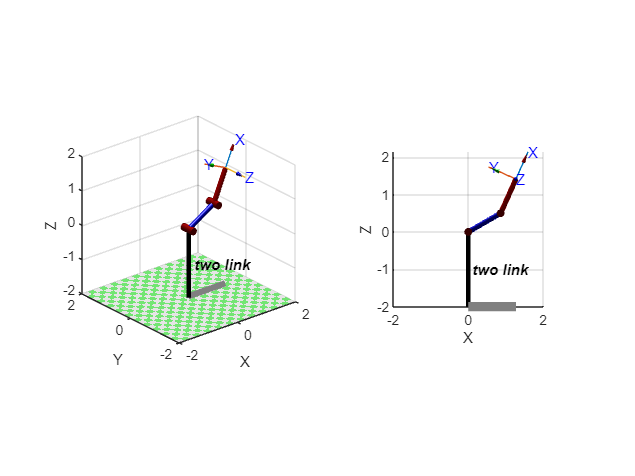

subplot(121)
twolink.plot([pi/6 pi/5],'view',[-40 25])
subplot(122)
twolink.plot([pi/6 pi/5])
axis([-0.5 2 -0.5 0.5 -0.5 2.5])
axis equal
view (0, 0)

### Forward Kinematics of Two Link Std.

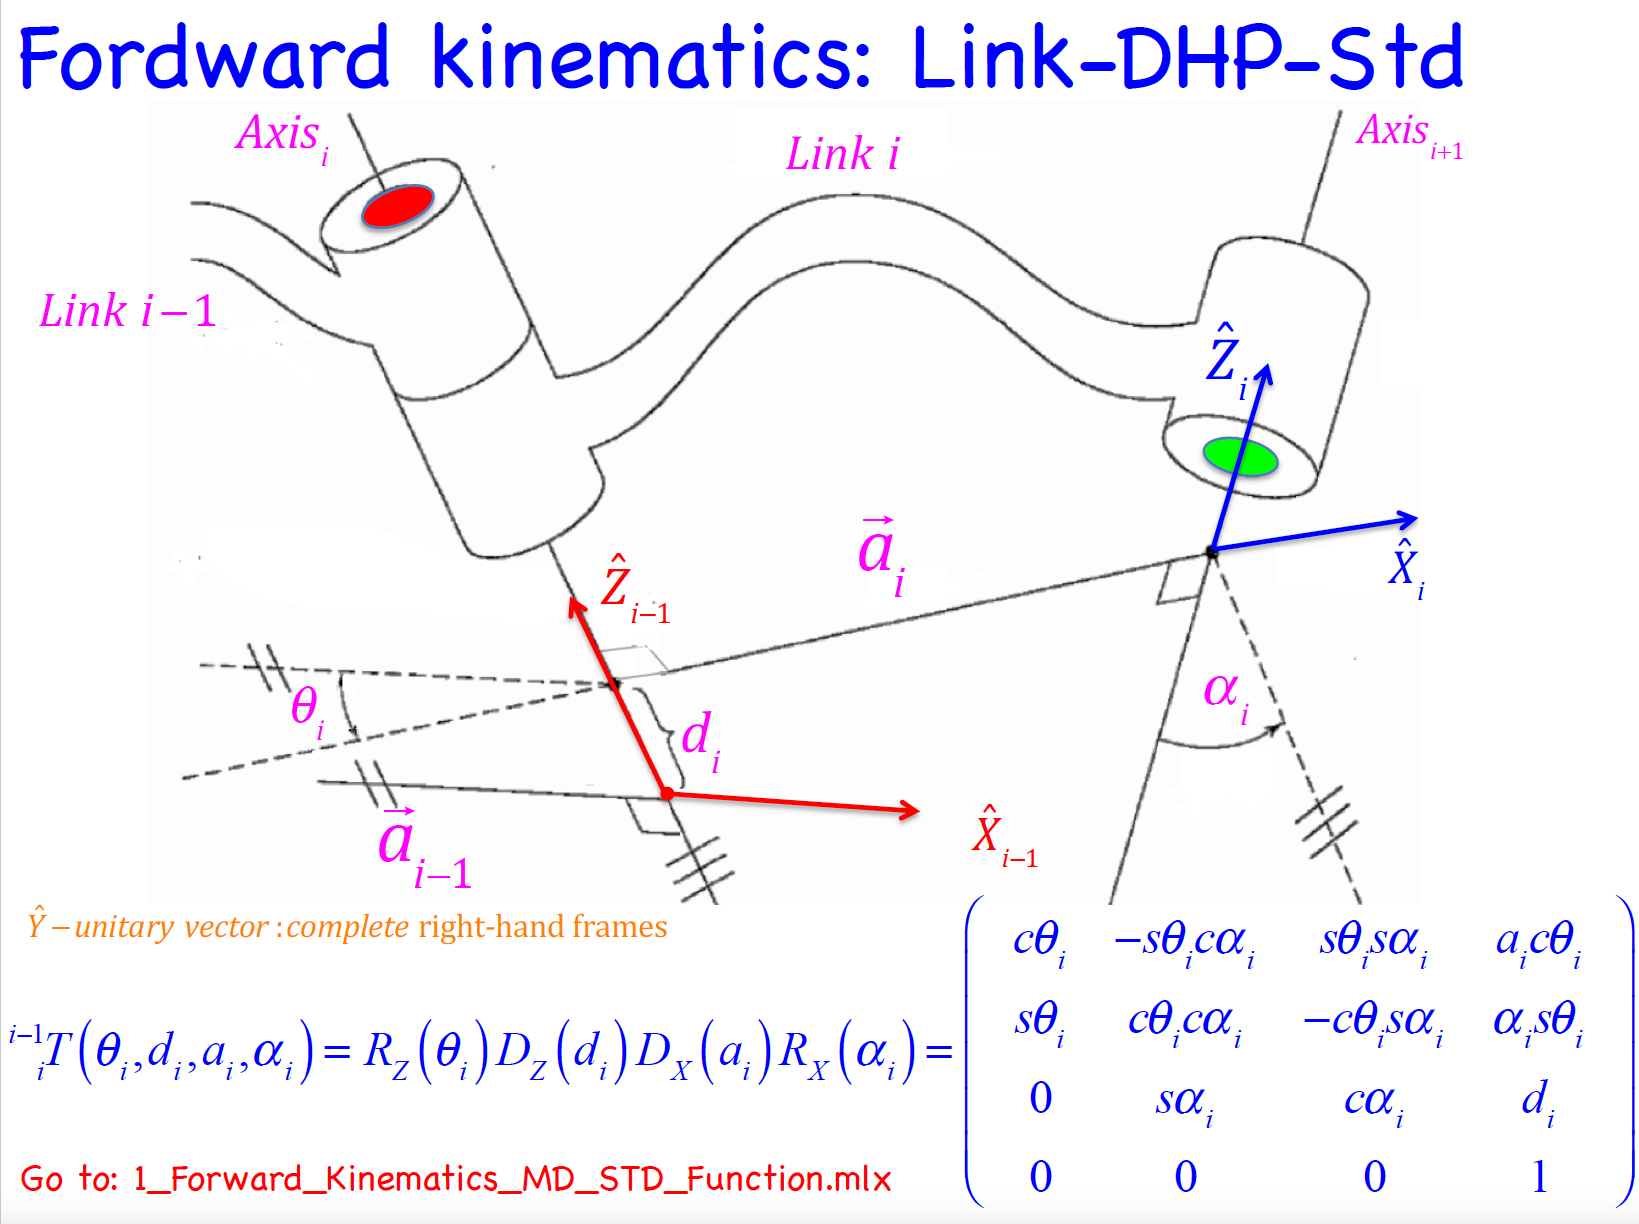

syms theta_1 theta_2 L_1 L_2 real
FK2L_Hand=simplify(troty(theta_1)*transl(L_1,0,0)*troty(theta_2)*transl(L_2,0,0))

$$FK2L\_Hand = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & 0 & \sin\left(\theta_{1}+\theta_{2}\right) & L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & \cos\left(\theta_{1}+\theta_{2}\right) & -L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-L_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

twolink.links(1, 1).a=L_1;
twolink.links(1, 2).a=L_2;
FK2L_RTB=simplify(twolink.fkine ([-theta_1 -theta_2]))

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & \sin\left(\theta_{1}+\theta_{2}\right) & 0 & L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)\\ 0 & 0 & -1 & 0\\ -\sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & -L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-L_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

###  System equation to solve

syms x z real %position of the {EE}
e1 = x == FK2L_RTB.t(1)

$$e1 = x=L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)$$

e2 = z == FK2L_RTB.t(3)

$$e2 = z=-L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-L_{1}\,\sin\left(\theta_{1}\right)$$

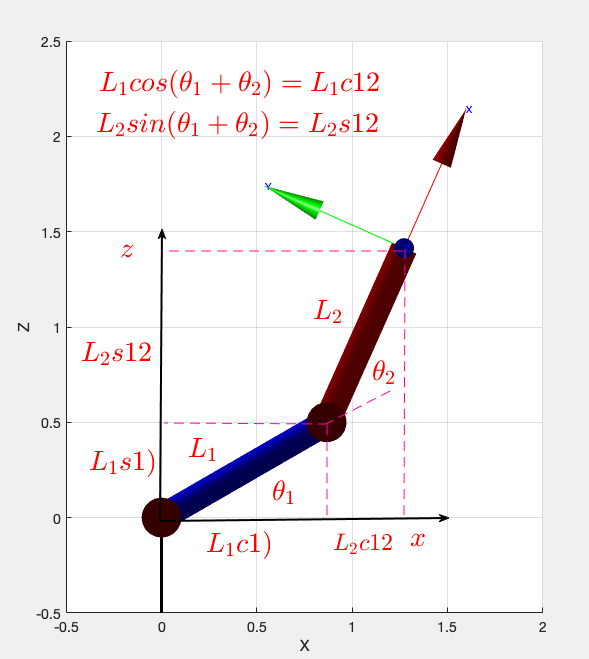

## Invers Kinematics by hand.

### Generate a known solution

clear
mdl_twolink
twolink.links(1, 1).a=1.5;
twolink.links(1, 2).a=1;
FD=twolink.fkine([pi/6 pi/5]);
XYZ=FD.t

XYZ =     1.7058
         0
    1.6635


Rotation=FD.R

Rotation =     0.4067   -0.9135         0
         0         0   -1.0000
    0.9135    0.4067         0


L1=twolink.links(1, 1).a

L1 = 1.5000

L2=twolink.links(1, 2).a

L2 = 1

#### Apply the theory

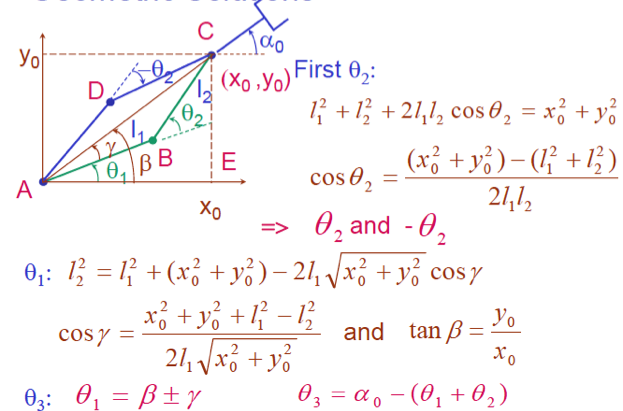

theta_2=acos(((XYZ(1)^2+XYZ(3)^2) -(L1^2+L2^2))/(2*L1*L2))

theta_2 = 0.6283

beta=atan2(XYZ(3),XYZ(1))

beta = 0.7729

gamma=acos((XYZ(1)^2+XYZ(3)^2+L1^2-L2^2)/(2*L1*sqrt((XYZ(1)^2+XYZ(3)^2))))

gamma = 0.2493

theta_1_1=beta+gamma

theta_1_1 = 1.0221

theta_1_2=beta-gamma

theta_1_2 = 0.5236

pi/6

ans = 0.5236

pi/5

ans = 0.6283

#### Testing solutions. See {EE}

XYZ

XYZ =     1.7058
         0
    1.6635


FD=twolink.fkine([pi/6 pi/5]);
FD_1=twolink.fkine([theta_1_1 -theta_2])

 

FD_1 = 
    0.9235   -0.3837         0     1.706
         0         0        -1         0
    0.3837    0.9235         0     1.664
         0         0         0         1


FD_2=twolink.fkine([theta_1_2 +theta_2])

 

FD_2 = 
    0.4067   -0.9135         0     1.706
         0         0        -1         0
    0.9135    0.4067         0     1.664
         0         0         0         1


## Invers Kinematics using RTB

At command windows: 

help SerialLink/ikine

### Generate a known solution

clear
mdl_twolink
FD=twolink.fkine([pi/6 pi/5])

 

FD = 
    0.4067   -0.9135         0     1.273
         0         0        -1         0
    0.9135    0.4067         0     1.414
         0         0         0         1


### Invoque ikine function

At command windows: help SerialLink/ikine to know more...it is a recursive numerical approach

#### Elbow down

Qd=twolink.ikine(FD,'mask',[1 1 0 0 0 0 ], 'q0',[0 0])

Qd =     0.5236    0.6283


[pi/6 pi/5]

ans =     0.5236    0.6283


#### Elbow up

Qu=twolink.ikine(FD,'mask',[1 1 0 0 0 0 ], 'q0',[pi/2 0])

Qu =     1.1519   -0.6283


### Ploting both solutions

Clone the twolink

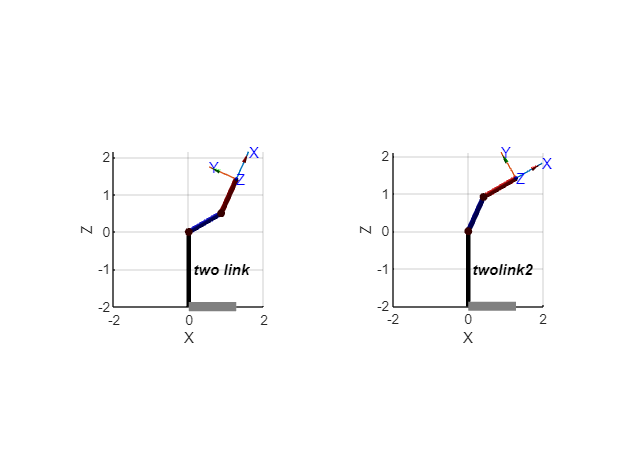

twolink2= SerialLink(twolink, 'name', 'twolink2');
subplot(121)
twolink.plot(Qd)
axis([-0.5 2 -0.5 0.5 -0.5 2.5])
axis equal
view (0, 0)
subplot(122)
twolink2.plot(Qu)
axis([-0.5 2 -0.5 0.5 -0.5 2.5])
axis equal
view (0, 0)

## Inverse Kinematics of Puma560

At command windows: 

help SerialLink/ikine6s

clear
mdl_puma560
bob= SerialLink(p560, 'name', 'bob'); % clone puma 560
qn 

qn =          0    0.7854    3.1416         0    0.7854         0


T1 = p560.fkine(qn)% Pose or Frame description

 

T1 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


qi1 = p560.ikine6s(T1,'ru')

qi1 =    -0.0000    0.7854    3.1416   -0.0000    0.7854    0.0000


qi2 = p560.ikine6s(T1,'rd')

qi2 =    -0.0000   -0.8335    0.0940   -3.1416    0.8312    3.1416



T2 = p560.fkine(qi1) % is equal to T1 !!!

 

T2 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1



T3 = p560.fkine(qi2) % is equal to T1 !!!

 

T3 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


T1

 

T1 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


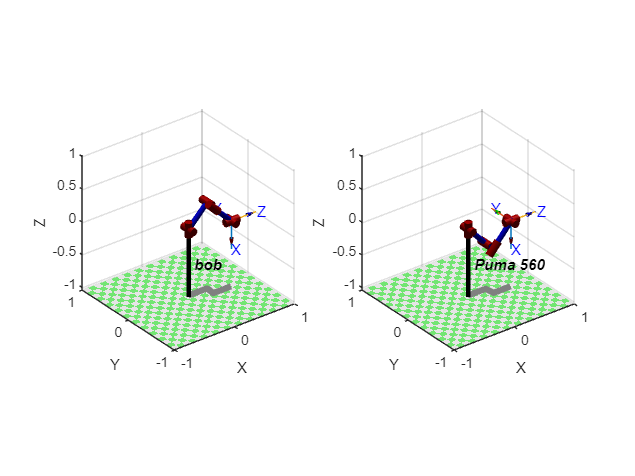

figure
subplot(121)
bob.plot(qi1)
subplot(122)
p560.plot(qi2)

## Practicing with ikine6s & p560.plot3d(qx)

Display the 8 solutions for qn (joint space). 

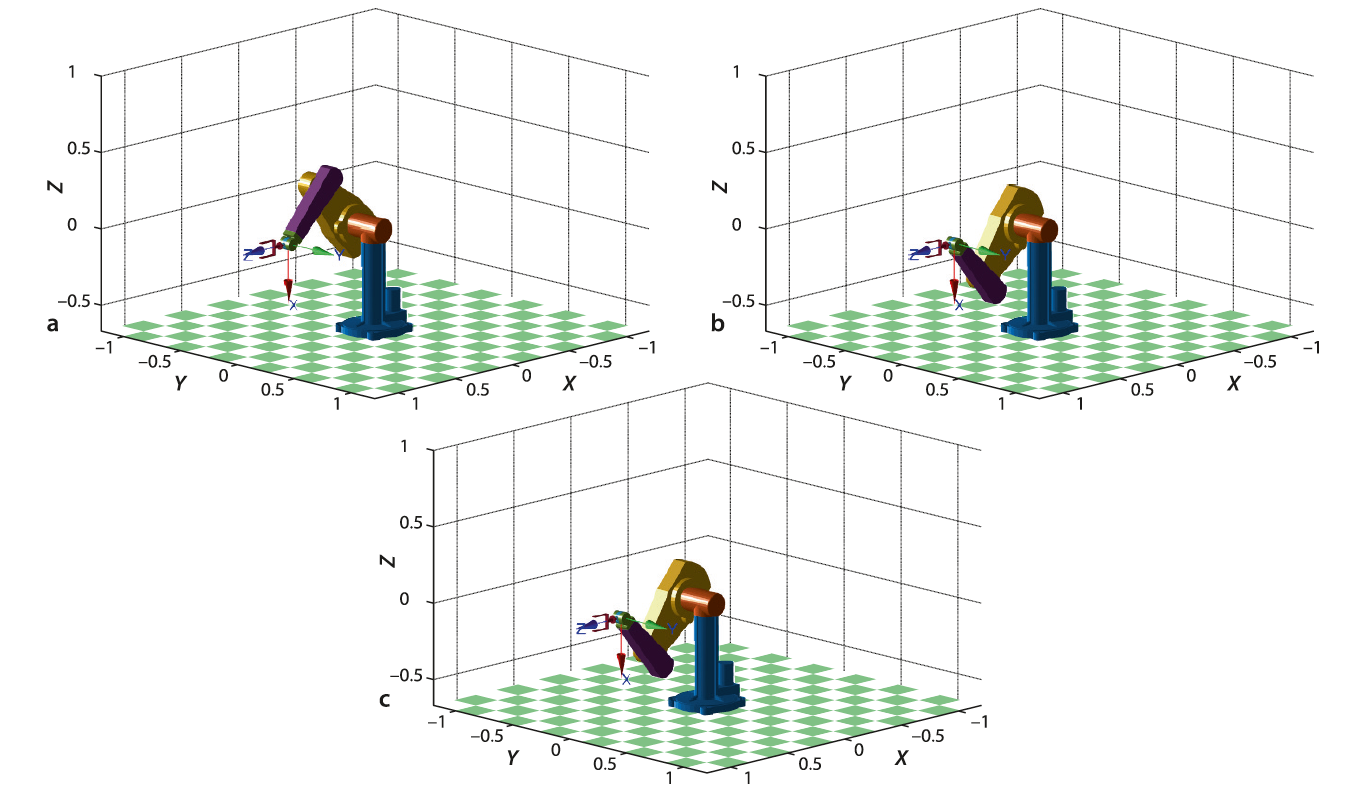

Different configurations of the Puma 560 robot.

a)  Rightup-noflip; 

b)  Right-down-noflip;

c)  Right-down-flip

## Get a pose

clear
mdl_puma560
T=p560.fkine(qn)

 

T = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


## Clone the Puma

p560LUF= SerialLink(p560, 'name', 'p560luf');
p560LUN= SerialLink(p560, 'name', 'p560lun');

Try also:

LDF, LDN, RUF, RUN, RDF, RDN

## Get different solutions

help seriallink/ikine6s to get familiar with the ikine function.

Q = R.ikine6s(T, CONFIG) as above but specifies the configuration of the arm in

  the form of a string containing one or more of the configuration codes:

  'l'   arm to the left (default)

  'r'   arm to the right

  'u'   elbow up (default)

  'd'   elbow down

  'n'   wrist not flipped (default)

  'f'   wrist flipped (rotated by 180 deg)

qiluf = p560.ikine6s(T, 'luf')

qiluf =     2.6486   -3.9270    0.0940   -0.6090   -0.9743   -2.7682


qilufdeg=qiluf*180/pi

qilufdeg =   151.7514 -225.0000    5.3833  -34.8950  -55.8261 -158.6058


qilun = p560.ikine6s(T, 'lun')

qilun =     2.6486   -3.9270    0.0940    2.5326    0.9743    0.3734


qilundeg=qilun*180/pi

qilundeg =   151.7514 -225.0000    5.3833  145.1050   55.8261   21.3942


## Plotting Puma configuration

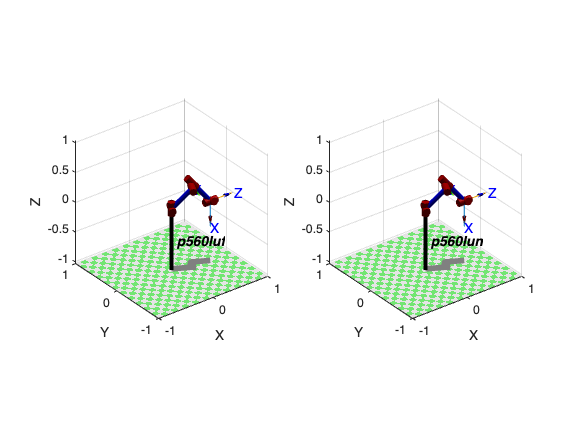

subplot(121)
p560LUF.plot(qiluf)
subplot(122)
p560LUN.plot(qilun)

## Play with teach 

Get inside of the concept wrist fliped 

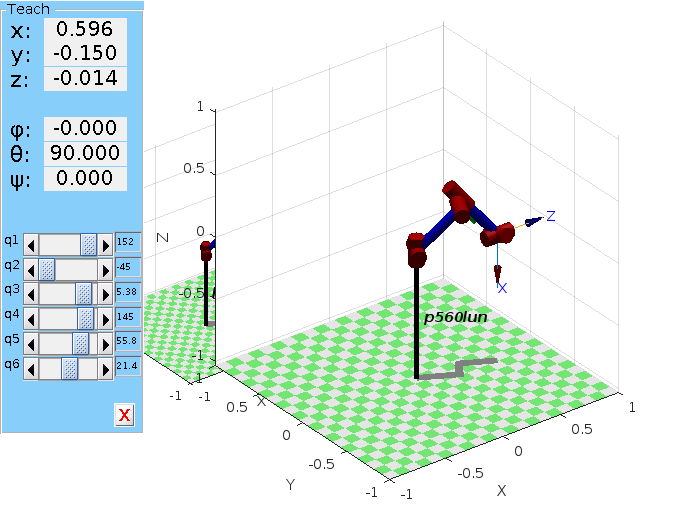

figure
p560LUN.teach(qilun,'eul')